**Testul 2**

Sa se aproximeze functia f : [−π, π] → R, f(x) = x + cos x^2 . 

a) Folosind toate cele patru tipuri de spline, noduri echidistante si noduri Cebisev de speta I, n = 10. 

clf;
a = -pi;
b = pi;
xx = linspace(a, b, 200);
n = 10;

f = @(x) x + cos(x.^2);
df = @(x) 1 - 2 .* x.* sin(x .^ 2 );
ddf = @(x) - 2 .* sin(x .^ 2 ) - 4 .* x .^2 .* cos(x .^ 2);

Pentru noduri echidistante:

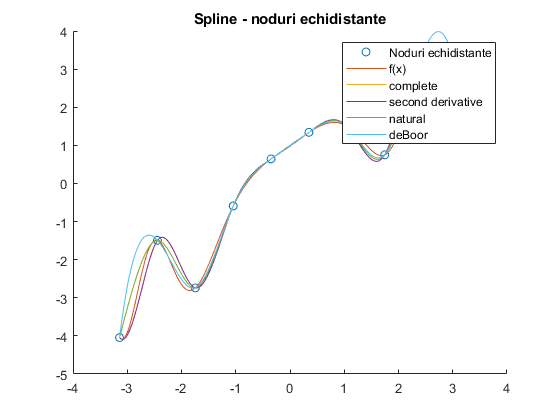

% Generare noduri echidistante
x = linspace(a, b, n);
y = f(x);

aa = CubicSpline(x, y, 0, [df(a), df(b)]);
yy_complete = eval_spline(x, aa, xx);

bb = CubicSpline(x, y, 1, [ddf(a), ddf(b)]);
yy_second_derivative = eval_spline(x, bb, xx);

c = CubicSpline(x, y, 2);
yy_natural = eval_spline(x, c, xx);

d = CubicSpline(x, y, 3);
yy_deboor = eval_spline(x, d, xx);

figure(1);
hold on;
plot(x, y, 'o');
plot(xx, f(xx));
plot(xx, yy_complete);
plot(xx, yy_second_derivative);
plot(xx, yy_natural);
plot(xx, yy_deboor);
legend('Noduri echidistante', 'f(x)', 'complete', 'second derivative', 'natural', 'deBoor');
title('Spline - noduri echidistante');

Pentru noduri Cebisev de speta I

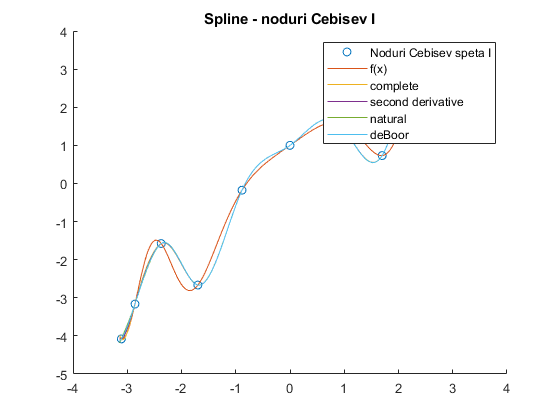

% Generare noduri Cebisev de speta I
x = 1/2*(a+b) + 1/2*(b-a)*cos(((2*[0:n] + 1)*pi/(2*n + 2)));
x = sort(x);  % sortare
y = f(x);

aa = CubicSpline(x, y, 0, [df(a), df(b)]);
yy_complete = eval_spline(x, aa, xx);

bb = CubicSpline(x, y, 1, [ddf(a), ddf(b)]);
yy_second_derivative = eval_spline(x, bb, xx);

c = CubicSpline(x, y, 2);
yy_natural = eval_spline(x, c, xx);

d = CubicSpline(x, y, 3);
yy_deboor = eval_spline(x, d, xx);

figure(2);
hold on;
plot(x, y, 'o');
plot(xx, f(xx));
plot(xx, yy_complete);
plot(xx, yy_second_derivative);
plot(xx, yy_natural);
plot(xx, yy_deboor);

legend('Noduri Cebisev speta I', 'f(x)', 'complete', 'second derivative', 'natural', 'deBoor');
title('Spline - noduri Cebisev I');

b) Folosind metoda celor mai mici patrate discreta si noduri Cebisev de speta II, n = 10. 

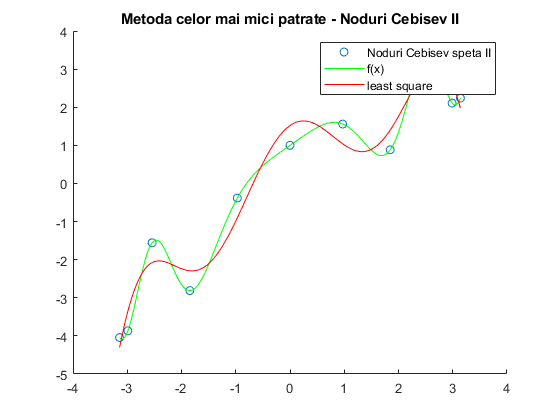

% Generare noduri Cebisev de speta II
x = 1/2*(a+b) + 1/2*(b-a)*cos([0:n]*pi/n);
x = sort(x);
y = f(x);

p = [1:n-1]; % gradul aproximantei < nr.obs-1
E = [ones(size(x')), x'.^p];

c = E\y'; % solve system E*c = y

yy_cheb = [ones(size(xx')), xx'.^p]*c;

figure(3);
hold on;
plot(x, y, 'o');
plot(xx, f(xx), 'g');
plot(xx, yy_cheb, 'r');
legend('Noduri Cebisev speta II', 'f(x)', 'least square');
title('Metoda celor mai mici patrate - Noduri Cebisev II');